# Unidad 6 - TP08b

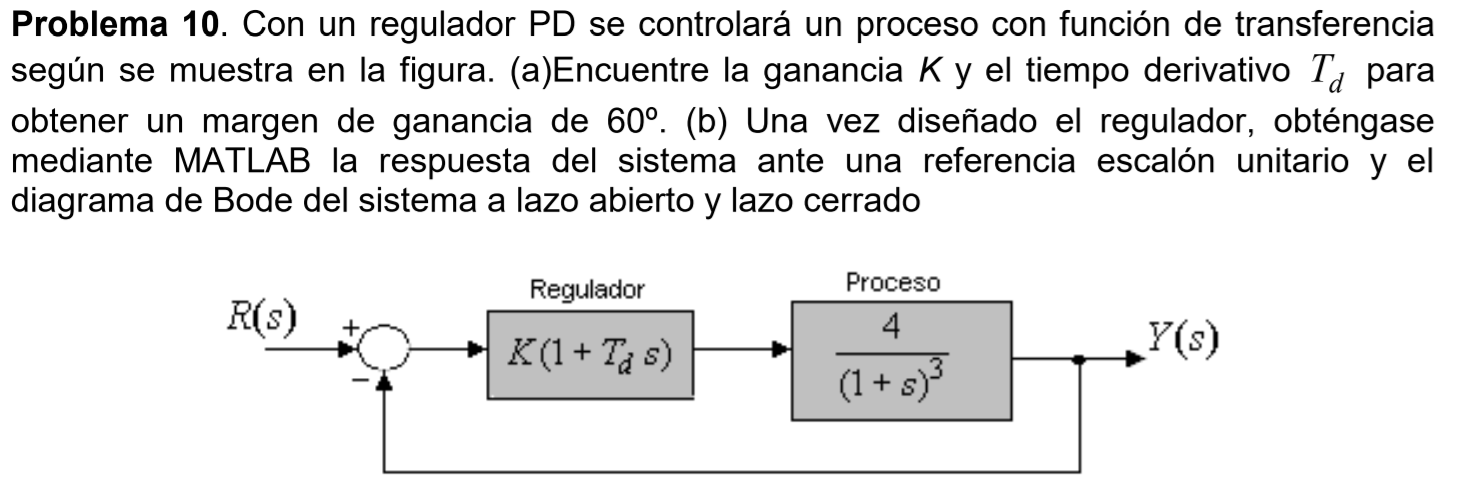

## Requisitos

- 
$$\textrm{MF}=60°$$


## Controlador Derivativo

Comenzamos analizando la planta


$$G\left(s\right)=\frac{4}{{\left(s+1\right)}^3 }$$


clear;
s = tf('s');
G = 4 / (s+1)^3;
H = 1;
margin(G*H);
grid on;

Observamos que para poder llegar al MF debemos diseñar a $w_d =0\ldotp 84\;\frac{\textrm{rad}}{s}$ y a esa frecuencia debemos atenuar la planta $\left|G\left(w_d \right)\right|=5\;\mathrm{dB}$.

Recordando nuestro controlador,


$$G_c \left(s\right)=k\;\left(T_d \;s+1\right)$$



$$G_c \left(s\right)=k\;T_d \left(s+\frac{1}{T_d }\right)$$



$$G_c \left(s\right)=k_d \;\left(s+z\right)$$



$$k_d =k\;T_d$$



$$z=\frac{1}{T_d }$$


Quedando entonces, 

z = 0.84
kd = 10 ^ (-5/20)
Td = 1/z
k = kd / Td

## Verificamos

Gc = kd * (s+z)
M = feedback(G, H);
Mc = feedback(Gc*G, H);

% MG y MF
margin(Gc*G);
grid on;

% Respuesta al escalón
step(M, Mc);
grid on;
legend("Sin compensar", "Compensado");

% Bode
bode(Gc*G, Mc);
grid on;
legend("Lazo abierto", "Lazo cerrado");